e = exp(1);
t = linspace(0,10)

t =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495


% y = -0.02*e.^(-9*t) + 0.18 * e.^(-t);
% plot(t,y,'bo') % overdamping system
% 
% hold on

e = exp(1);
t = linspace(0,10)

t =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495


% y = (0.16 + 0.48*t).*e.^(-3*t);
% plot(t,y) % Critical Damping system
% 
% hold on

p = [1 1 9];
b = roots(p)

b =   -0.5000 + 2.9580i
  -0.5000 - 2.9580i


a = (0.5*0.16)/(2.958)

a = 0.0270

c = sqrt((0.16)^2 + (0.027)^2)

c = 0.1623

e = exp(1);
t = linspace(0,10,200);
y = 0.1623.*(e.^(-0.5*t)).*cos(2.958*t - 0.17);
y2 = 0.1623.*(e.^(-0.5*t))

y2 =     0.1623    0.1583    0.1543    0.1505    0.1468    0.1431    0.1396    0.1361    0.1327    0.1295    0.1262    0.1231    0.1201    0.1171    0.1142    0.1113    0.1086    0.1059    0.1033    0.1007    0.0982    0.0958    0.0934    0.0911    0.0888    0.0866    0.0845    0.0824    0.0803    0.0783    0.0764    0.0745    0.0726    0.0708    0.0691    0.0674    0.0657    0.0641    0.0625    0.0609    0.0594    0.0579    0.0565    0.0551    0.0537    0.0524    0.0511    0.0498    0.0486    0.0474


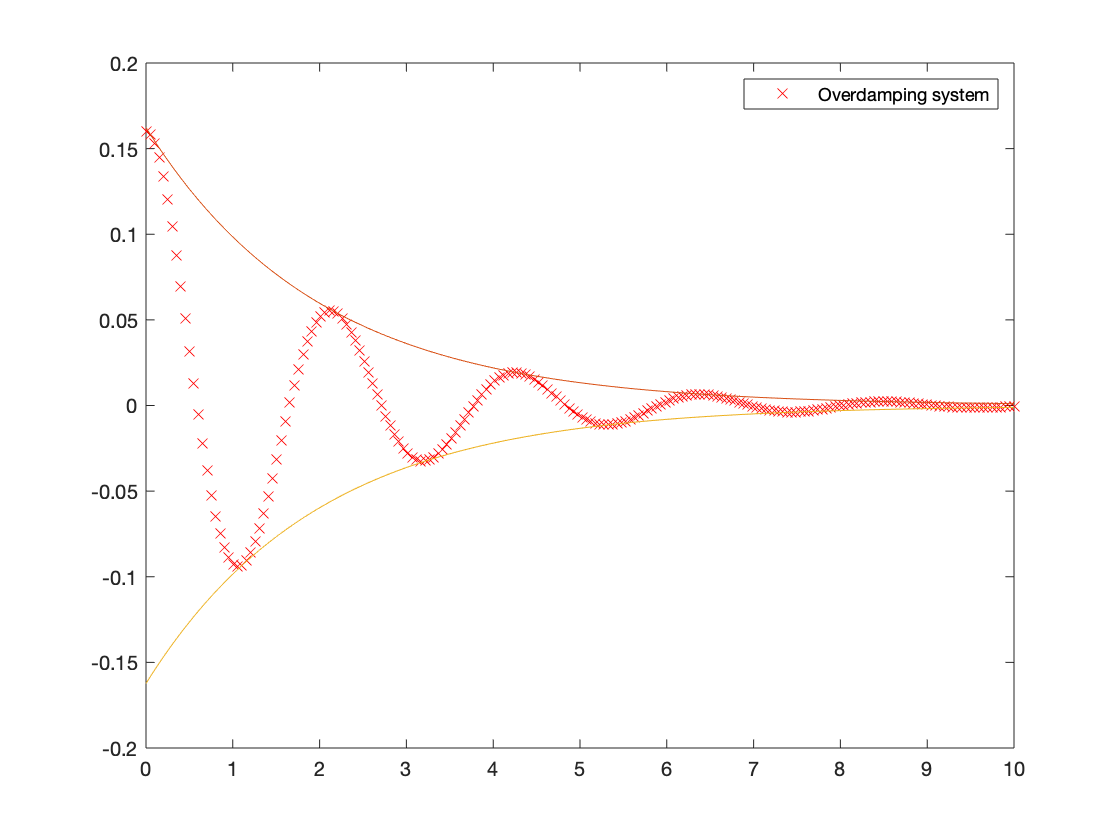

plot(t,y,'rx')
hold on
plot(t,y2)
hold on
plot(t,-y2)
legend('Overdamping system')%,'Critical Damping System','Underdamping system')

x = linspace(200,2000,10);
disp(x)

  Columns 1 through 9

         200         400         600         800        1000        1200        1400        1600        1800

  Column 10

        2000



y = 0.0012*x + 2.2979;
disp(y)

    2.5379    2.7779    3.0179    3.2579    3.4979    3.7379    3.9779    4.2179    4.4579    4.6979



z = 0.1023*x - 0.1111;
disp(z)

   20.3489   40.8089   61.2689   81.7289  102.1889  122.6489  143.1089  163.5689  184.0289  204.4889



num = [1 20];
den = [1 8 25 0];
FT = tf(num,den);
syms s t
snum = poly2sym(num,s);
sden = poly2sym(den,s);

% Step Function
FT_time_domain = ilaplace(snum/sden)

$$FT\_time\_domain = \frac{4}{5}-\frac{4\,{\mathrm{e}}^{-4\,t}\,\left(\cos\left(3\,t\right)+\frac{11\,\sin\left(3\,t\right)}{12}\right)}{5}$$

num = [1 20];
den = [1 8 25];
FT = tf(num,den);
syms s t
snum = poly2sym(num,s);
sden = poly2sym(den,s);

%Impulse Function
FT_time_domain = ilaplace(snum/sden)

$$FT\_time\_domain = {\mathrm{e}}^{-4\,t}\,\left(\cos\left(3\,t\right)+\frac{16\,\sin\left(3\,t\right)}{3}\right)$$

% FT_time_domain = simplify(FT_time_domain, 'Steps',0)
% FT_time_domain = collect(FT_time_domain, exp(-t))